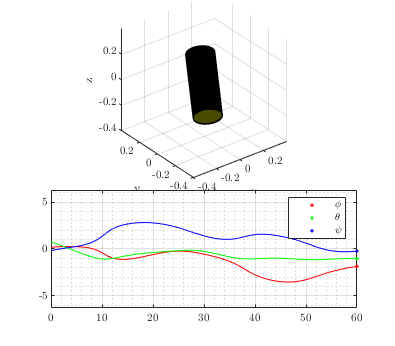

%% AE6210 Advanced Dynamics
% Spacecraft Attitude Dynamics Animation Code
% Tomoki Koike

clear; close all; clc;

% Load data
load simres.mat
angles = res.orient(:,4:end);

% Reference position
r = [0; 0; 0];

% Cylinder spec
Radius = 0.1;
Height = 0.5;
SideCount = 100;

% Vertices
vertices_0 = zeros(2*SideCount, 3);
for i = 1:SideCount
    theta = 2*pi/SideCount*(i-1);
    vertices_0(i,:) = [Radius*cos(theta), Radius*sin(theta), r(3)+Height/2];
    vertices_0(SideCount+i,:) = [Radius*cos(theta), Radius*sin(theta), r(3)-Height/2];
end

% Side faces
sideFaces = zeros(SideCount, 4);
for i = 1:(SideCount-1)
    sideFaces(i,:) = [i, i+1, SideCount+i+1, SideCount+i];
end
sideFaces(SideCount,:) = [SideCount, 1, SideCount+1, 2*SideCount];

% Bottom faces
bottomFaces = [
    1:SideCount;
    (SideCount+1):2*SideCount];

figure("Position",[10 10 800 700]);
% Initial
% Reference orientation
R = eul2rotm([angles(1,1), angles(1,2), angles(1,3)],"ZYX");
vertices = r' + vertices_0*R';

subplot(2,1,1)
% Draw patches
h_side = patch('Faces', sideFaces, 'Vertices', vertices, 'FaceColor', 'b');
h_bottom = patch('Faces', bottomFaces, 'Vertices', vertices, 'FaceColor', 'y');

% Axes settings
xlabel('x'); ylabel('y'); zlabel('z');
axis vis3d equal;
view([-37.5, 30]);
camlight;
grid on;
xlim([-0.4, 0.4]);
ylim([-0.4, 0.4]);
zlim([-0.4, 0.4]);

subplot(2,1,2)
hh1(1) = line(t.orient(1), res.orient(1,4), 'Color', 'r', 'LineStyle', 'none', 'Marker', '.');
hh1(2) = line(t.orient(1), res.orient(1,5), 'Color', 'g', 'LineStyle', 'none', 'Marker', '.');
hh1(3) = line(t.orient(1), res.orient(1,6), 'Color', 'b', 'LineStyle', 'none', 'Marker', '.');
hh2(1) = line(t.orient(1), res.orient(1,4), 'Color', 'r');
hh2(2) = line(t.orient(1), res.orient(1,5), 'Color', 'g');
hh2(3) = line(t.orient(1), res.orient(1,6), 'Color', 'b');
ylim([-2*pi,2*pi])
legend('$\phi$','$\theta$','$\psi$')
grid on; grid minor; box on;

for i = 2:length(angles(:,1))
    % Reference orientation
    R = eul2rotm([angles(i,1), angles(i,2), angles(i,3)],"ZYX");
    vertices = r' + vertices_0*R';
    
    % Draw patches
    set(h_side,'Vertices',vertices);
    set(h_bottom,'Vertices',vertices);

    % Update angles
    set(hh1(1), 'XData', t.orient(i), 'YData', res.orient(i,4));
    set(hh1(2), 'XData', t.orient(i), 'YData', res.orient(i,5));
    set(hh1(3), 'XData', t.orient(i), 'YData', res.orient(i,6));
    set(hh2(1), 'XData', t.orient(1:i), 'YData', res.orient(1:i,4));
    set(hh2(2), 'XData', t.orient(1:i), 'YData', res.orient(1:i,5));
    set(hh2(3), 'XData', t.orient(1:i), 'YData', res.orient(1:i,6));

    drawnow;
end